# Control Theory

# Laboratory 1

Mikołaj Suchoń and Witold Surdej

## Task 1)

## A)

clear
syms('DampRatio')
K=1;
D=0;
num=K;
T1=0.02;
T2=0.002;
den=[T1*T2,T1+T2,1,0];
sys=tf(num,den);
Mpw=1.84;
eq= Mpw==(2*DampRatio*sqrt(1-DampRatio^2))^-1

$$eq = \frac{46}{25}=\frac{1}{2\,\mathrm{DampRatio}\,\sqrt{1-{\mathrm{DampRatio}}^{2}}}$$

eq2= -Mpw==(2*DampRatio*sqrt(1-DampRatio^2))^-1

$$eq2 = -\frac{46}{25}=\frac{1}{2\,\mathrm{DampRatio}\,\sqrt{1-{\mathrm{DampRatio}}^{2}}}$$


s=solve(eq,DampRatio)

$$s = \left(\begin{array}{c} \frac{\sqrt{-\frac{625}{23\,\left(\sqrt{1491}-46\right)}}}{2}\\ \frac{25\,\sqrt{23}}{46\,\sqrt{\sqrt{1491}+46}} \end{array}\right)$$

s2=solve(eq2,DampRatio)

$$s2 = \left(\begin{array}{c} -\frac{\sqrt{-\frac{625}{23\,\left(\sqrt{1491}-46\right)}}}{2}\\ -\frac{25\,\sqrt{23}}{46\,\sqrt{\sqrt{1491}+46}} \end{array}\right)$$

ss=[s;s2]

$$ss = \left(\begin{array}{c} \frac{\sqrt{-\frac{625}{23\,\left(\sqrt{1491}-46\right)}}}{2}\\ \frac{25\,\sqrt{23}}{46\,\sqrt{\sqrt{1491}+46}}\\ -\frac{\sqrt{-\frac{625}{23\,\left(\sqrt{1491}-46\right)}}}{2}\\ -\frac{25\,\sqrt{23}}{46\,\sqrt{\sqrt{1491}+46}} \end{array}\right)$$

var = vpa(ss)

$$var = \left(\begin{array}{c} 0.959015965051720659303678252829\\ 0.28335204035954443610666490435945\\ -0.959015965051720659303678252829\\ -0.28335204035954443610666490435945 \end{array}\right)$$

## B)

damping_ratio = 0.2834; % check this damping ratio value.

% wn = 0:100:400;
% rlocus(sys);
% axis([-520 20 -400 400])
% sgrid(damping_ratio, wn);
% [K, closed_loop_poles] = rlocfind(sys)
% Aready extracted K from rlocfind:
newData1 = load('-mat', 'K');
vars = fieldnames(newData1);
assignin('base', vars{3}, newData1.(vars{3}));
K

K = 99.4474

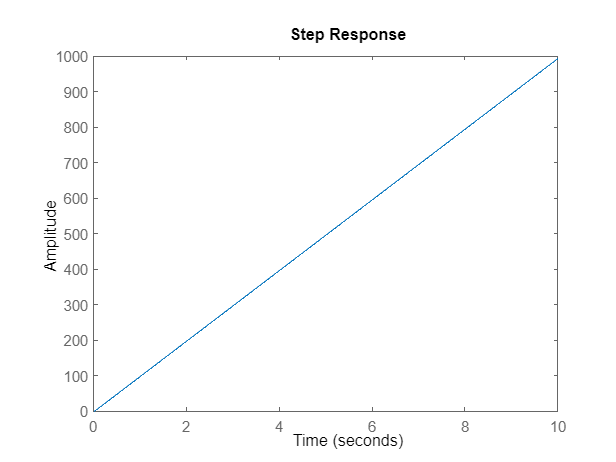

sys2=tf(K,den);
step(sys2)

sys_closed=feedback(sys2,1)

sys_closed =
 
                99.45
  ---------------------------------
  4e-05 s^3 + 0.022 s^2 + s + 99.45
 
Continuous-time transfer function.



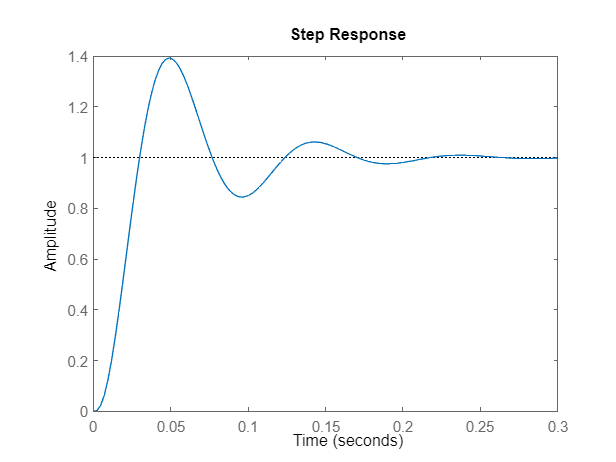


[y,tOut]=step(sys_closed);step(sys_closed)

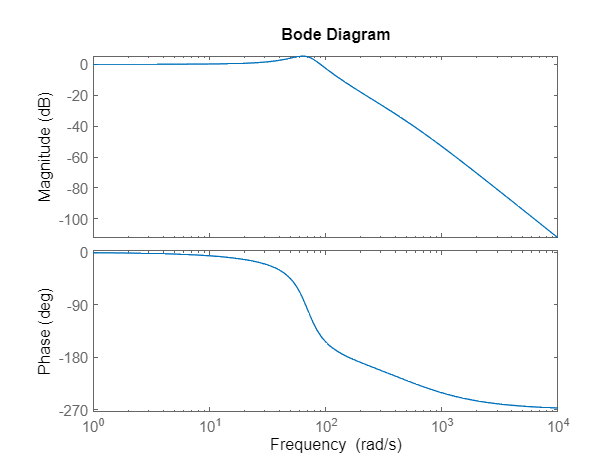

bode(sys_closed);

Solving 20*log(|T|)=5.3 we obtain    ~T=1.84

T=1.84;

## C)

S=1-sys_closed

S =
 
      4e-05 s^3 + 0.022 s^2 + s
  ---------------------------------
  4e-05 s^3 + 0.022 s^2 + s + 99.45
 
Continuous-time transfer function.



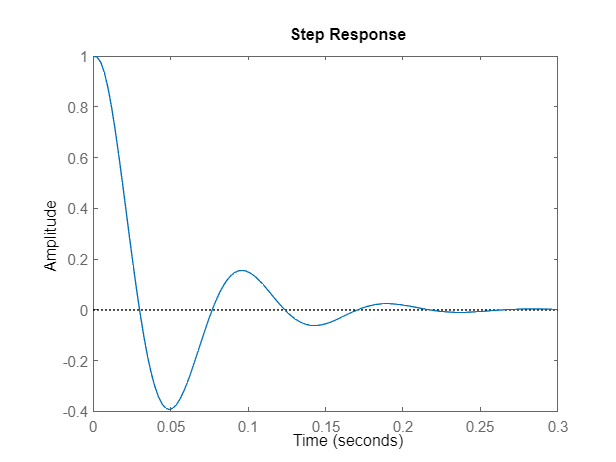

step(S)

wb=120;
[mag, phase, wout] = bode(S);
[~,phase1]=bode(S,wb);
[~,phase2]=bode(S,wb/2);
[~,phase3]=bode(S,wb/4);


mag_db = 20*log10(mag);
figure;
subplot(2,1,1);
magdb=mag_db(1,:);
% semilogx(wout, magdb,'-',wb,mag1,'*',wb/2,mag2,'*',wb/3,mag3,'*');

From bode plot:

syms S
eq = 20*log10(abs(S))==3.2;
S1=vpa(solve(eq,S))

$$S1 = 1.4454397707459275119314815458354$$

eq = 20*log10(abs(S))==4.46;
S2=vpa(solve(eq,S))

$$S2 = 1.6710906143107075834731238646362$$

eq = 20*log10(abs(S))==-3.1;
S3=vpa(solve(eq,S))

$$S3 = 0.6998419960022734988243713460702$$

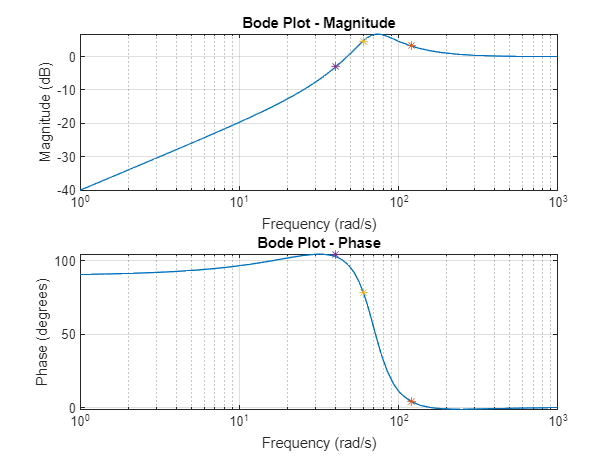

semilogx(wout, magdb,'-',wb,3.2,'*',wb/2,4.46,'*',wb/3,-3.1,'*');
grid on;
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('Bode Plot - Magnitude');

subplot(2,1,2);
phase=phase(1,:);

semilogx(wout, phase,'-',wb,phase1,'*',wb/2,phase2,'*',wb/3,phase3,'*');
grid on;
xlabel('Frequency (rad/s)');
ylabel('Phase (degrees)');
title('Bode Plot - Phase');

## D)

newData1 = load('-mat', 'K1');
vars = fieldnames(newData1);
assignin('base', vars{4}, newData1.(vars{3}));
K1

K1 = 13.0863

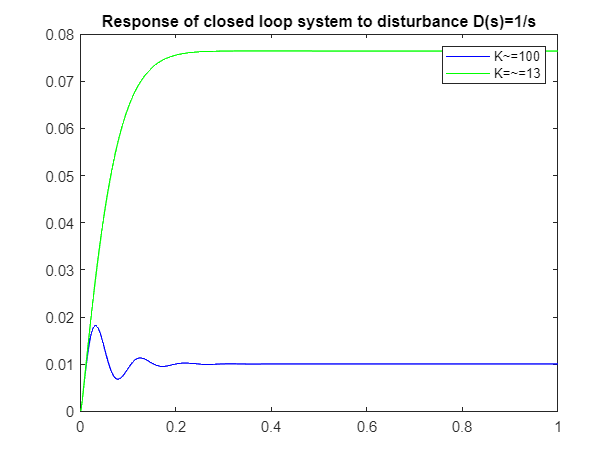


simou=sim("task1.slx");
figure
plot(simou.tout,simou.simout,'b',simou.tout,simou.simout1,'g')
title('Response of closed loop system to disturbance D(s)=1/s')
legend('K~=100','K=~=13')

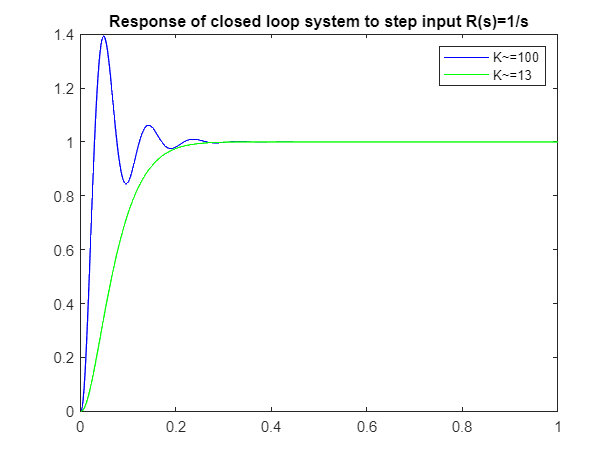

plot(simou.tout,simou.simout2,'b',simou.tout,simou.simout3,'g')
title('Response of closed loop system to step input R(s)=1/s')
legend('K~=100','K~=13')